# Data Analysis: Data Visualization

#### by Rodolfo Muñoz

Similar to the previous example, we're going to load the data from our spreadsheet into a table.

clear variables; close all; clc;
[filename,path] = uigetfile('*.xls');
colors = [0.4 0.5 1; 0 0 0];

tabds = datastore([path filename],'Type',"spreadsheet");

tabds.ReadSize = 'sheet';
preview(tabds)

ans = 8×21 table
    RowID         OrderID           OrderDate      ShipDate           ShipMode          CustomerID        CustomerName           Segment            Country                City                State         PostalCode     Region           ProductID              Category           Sub_Category                                  ProductName                                 Sales     Quantity    Discount    Profit 
    _____    __________________    ___________    ___________    __________________    ____________    __

For this analysis we'll look over the sales values so we'll retrieve only a handful of columns from the table.

tabds.SelectedVariableNames = {'OrderDate','CustomerID','Segment','Category','Sales','Quantity','Profit'};
tab = read(tabds);

## Customer Sales vs Profit

Scatter plot with the style of the Tableau software to get a quick grasp of profit margin of the sales per customer.

For that we group the sales data by customer and get their overall profit from all the items they've bought. 

tab_aux = tab(:,{'CustomerID','Sales','Profit','Quantity'});
sales = groupsummary(tab_aux,{'CustomerID'},'sum');
qty.max = max(sales.sum_Quantity);
qty.min = min(sales.sum_Quantity);
qty.relative = (sales.sum_Quantity-qty.min)/(qty.max-qty.min);
profit.ratio = sales.sum_Profit ./ sales.sum_Sales;
profit.minR = min(profit.ratio);
profit.maxR = max(profit.ratio);
profit.meanR = mean(profit.ratio);

Then, we define a colormap **color_map **for the points in the scatter plot based on the following criteria:

- Positive profits $\left(p_i \ge 0\right)$ are distribuited proportionally from $c_{\textrm{mid}}$, when there is no profit $\left(p_i =0\right)$, to $c_{\textrm{top}}$ when it corresponds to the maximum profit of the group $\left(p_i =p_{\max } \right)$

- Similarly, negative profits $\left(p_i <0\right)$ are distribuited proportionally from $c_{\textrm{mid}}$, when there is no profit $\left(p_i =0\right)$, to $c_{\textrm{bot}}$ when it corresponds to the minimum profit of the group $\left(p_i =p_{\min } \right)$

c_top = [65 150 230]/255;
c_mid = [250 190 135]/255;
c_bot = [145 45 15]/255;

colorpicker = @(x) (x>=0).*(x/profit.maxR*(c_top-c_mid) + c_mid) +...
                   (x<0).*(x/profit.minR*(c_bot-c_mid) + c_mid);
color_map = colorpicker(profit.ratio);      

Finally, we fit a **linear estimation** of profit vs sales. 

profit.fit = fit(sales.sum_Sales,sales.sum_Profit,'poly1');

And plot everything together. To improve how much data this visualization technique presents, we use the size of the circles as a measurement of how much items have been bought by each customer (total quantity).

scatter(sales.sum_Sales,sales.sum_Profit,1+100*(qty.relative/0.5).^2,color_map,'filled');
hold on;
line1 = plot(profit.fit,'black');
hold off;

Format the labels to fit the nature of the data and add the adapt the colorbar to our current color_map.

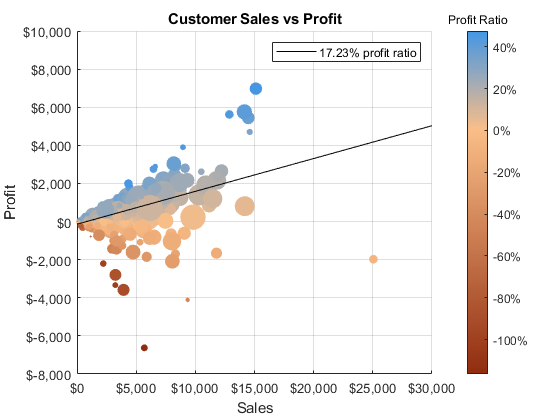

ytickformat('$%,g')
ylabel('Profit')
xtickformat('$%,g')
ax = gca;
ax.XAxis.Exponent = 0; 
xlabel('Sales')
title('Customer Sales vs Profit')
legend(line1,num2str(profit.fit.p1*100,'%.2f%% profit ratio'))
grid on;

colormap(colorpicker((profit.minR:0.01:profit.maxR)'));
c_bar = colorbar;
set(gca,'clim',100*[profit.minR profit.maxR]);
c_bar.Ruler.TickLabelFormat='%g%%';
c_bar.Title.String = 'Profit Ratio';
% fig2pdf('CustomerSalesVsProfit')

## Average ticket

See which is the average value of the items bought by the customers.

To do that, first we retrieve and group the data by customer type:

tab_aux = tab(:,{'CustomerID','Segment','Sales','Quantity'});
stats = grpstats(tab_aux(:,{'CustomerID','Sales','Quantity'}),{'CustomerID'},{'mean','sum'});
customers = groupsummary(tab_aux,{'CustomerID','Segment'});
[G,ID] = findgroups(customers.Segment);

groups = zeros(length(G),1);
for i=1:length(stats.CustomerID)
    groups(i) = G(strcmpi(customers.CustomerID,stats.CustomerID{i})); 
end

c_top = [65 150 230]/255;
c_mid = [250 190 135]/255;
c_bot = [145 45 15]/255;
colorpicker = @(x) (mod(x,3)==1)*c_top + (mod(x,3)==2)*c_mid + (mod(x,3)==0)*c_bot;
average_fit = fit(stats.sum_Quantity,stats.sum_Sales/1e3,'poly1');

Then, we check sales vs the amount of items bought by each customer to get the company's average ticket

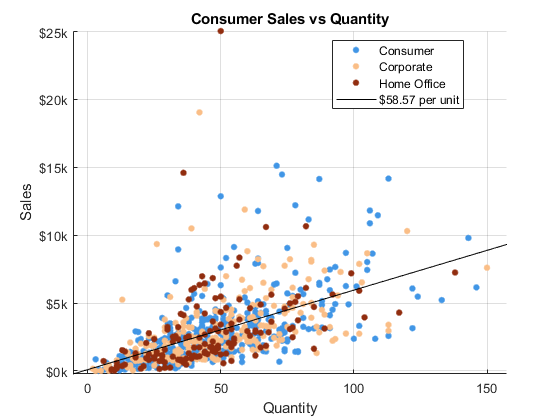

figure;
hold on;
gscatter(stats.sum_Quantity,stats.sum_Sales/1e3,groups,[c_top;c_mid;c_bot],".",15)
plot(average_fit,'k')
hold off
ylabel('Sales')
ytickformat('$%.0fk')
xlabel('Quantity')
title('Consumer Sales vs Quantity')
legend([ID; num2str(1e3*average_fit.p1,'$%.2f per unit')])
grid on, axis tight
% fig2pdf('CustomerSalesVsQuantity')

To complement the information, we do a scatter plot of each customer's average sales vs average number of items bought. In addition, we scale the size of the circles proportional to the total purchases made by each customer.

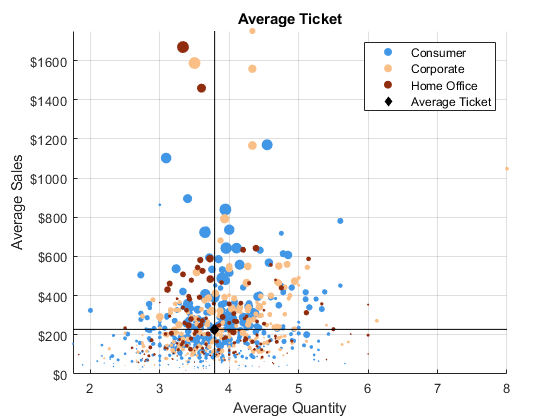

av_sales = mean(stats.mean_Sales);
av_qty= mean(stats.mean_Quantity);

figure;
hold on;
for i=1:length(ID)
    aux = stats.sum_Sales(groups==i);
    scatter(stats.mean_Quantity(groups==i),stats.mean_Sales(groups==i),80*aux/max(aux),colorpicker(i),'filled'); 
end
scatter(av_qty,av_sales,50,'black',"filled","d");
line([av_qty av_qty],[0 max(stats.mean_Sales)],'color','black');
line([min(stats.mean_Quantity) max(stats.mean_Quantity)],[av_sales av_sales],'color','black');
ylabel('Average Sales')
ytickformat('$%.0f')
xlabel('Average Quantity')
title('Average Ticket')
legend([ID; 'Average Ticket'])
grid on, axis tight, hold off
% fig2pdf('AverageTicket')

With that, we see that the average ticket of $58.57 usd is gotten from average purchases of around 3.8 items per sale. Also, we can see that there's a high concentration of high value customers (high total sales) around a mid area close to the average ticket. That is, most of the company's income comes from a target audience that buys each time an average of ~$150 to ~$600 usd between 3 to 5 items, in other words, most of the sales of the company come from items that cost around $30-$200 usd each.

Finally, we can see these average ticket filtered by each customer type to check if they have different behaviours: 

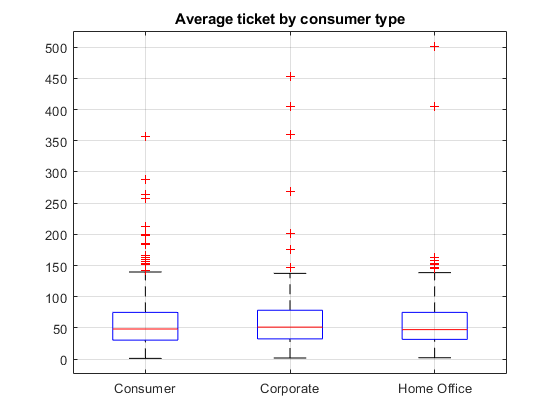

figure;
boxplot(stats.sum_Sales./stats.sum_Quantity,groups)
xticklabels(ID)
title('Average ticket by consumer type')
grid on;

By looking at the boxplot, we can say that in regards to the sales each customer type behaves very similarly with only ourliers as the main difference.

## Profit vs cost

Bar plots to check quickly how the margin of profit relates to the total effort (costs involved) made each year.

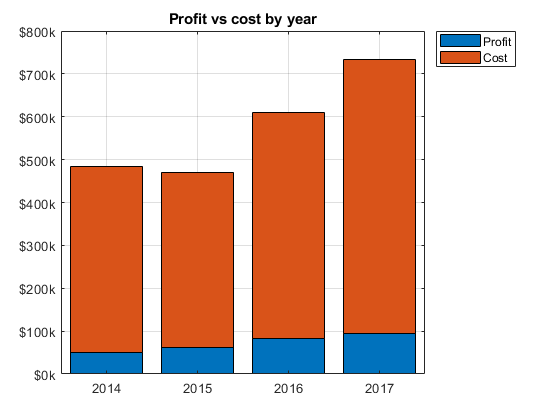

figure;
sum_y = groupsummary(tab(:,{'OrderDate','Sales','Profit'}),{'OrderDate'},["year"],'sum');
bar(sum_y.year_OrderDate,[sum_y.sum_Profit,sum_y.sum_Sales-sum_y.sum_Profit]/1e3,['stacked']);
ytickformat('$%.0fk')
legend({'Profit','Cost'},'Location','northeastoutside')
title('Profit vs cost by year')
grid on
% fig2pdf('ProfitVsCost')

While in the graph the profit doesn't seem to go up as much as the sales in the last 4 years, we can check that actually the company's has become more efficient and managed to improve its margin of profit:

sales_increase_percent = (sum_y.sum_Sales(end)/sum_y.sum_Sales(1)-1)*100

sales_increase_percent = 51.4133

profit_increase_percent = (sum_y.sum_Profit(end)/sum_y.sum_Profit(1)-1)*100

profit_increase_percent = 88.5987

profit_margin = sum_y.sum_Profit./sum_y.sum_Sales

profit_margin =     0.1023
    0.1310
    0.1343
    0.1274


margin_increase_percent = (profit_margin(end)/profit_margin(1)-1)*100

margin_increase_percent = 24.5588